# Lab 2

## Kurt Delegard

## PHYS 434 AB

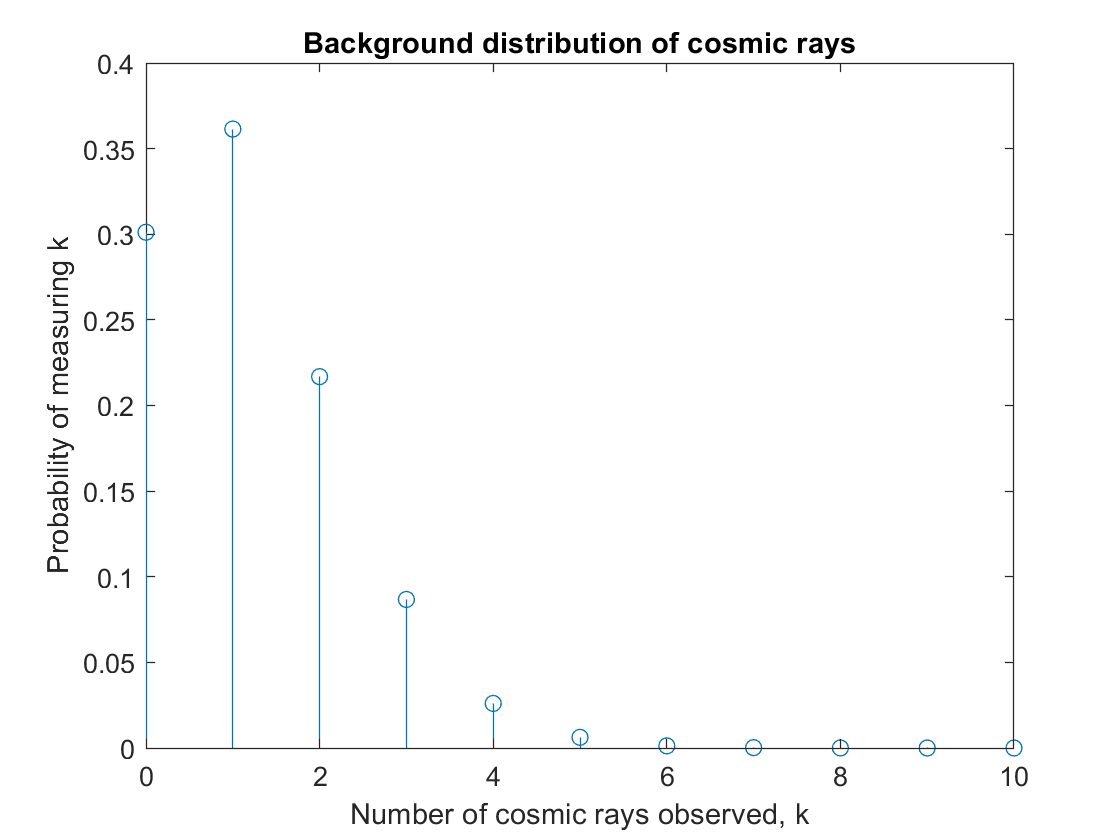

clear;
clf;


%Average cosmic rays per day (background)
X = 1.2;

%Average number of gamma ray emitted by source
Y = 4.0;

pd_bkg = makedist('Poisson', X);
xs = 0:10;
%pd_ys = random(pd_bkg, [1,100000]);
pd_ys = pdf(pd_bkg, xs);
stem(xs, pd_ys);
%histogram(pd_ys, 'binmethod', 'integers', 'Normalization', "pdf")
title('Background distribution of cosmic rays');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');

%xlim([0 10])
%xlim([-0.68 10])

Now we will see how the probability distribution changes as we convolve (sum) the distribution over time:

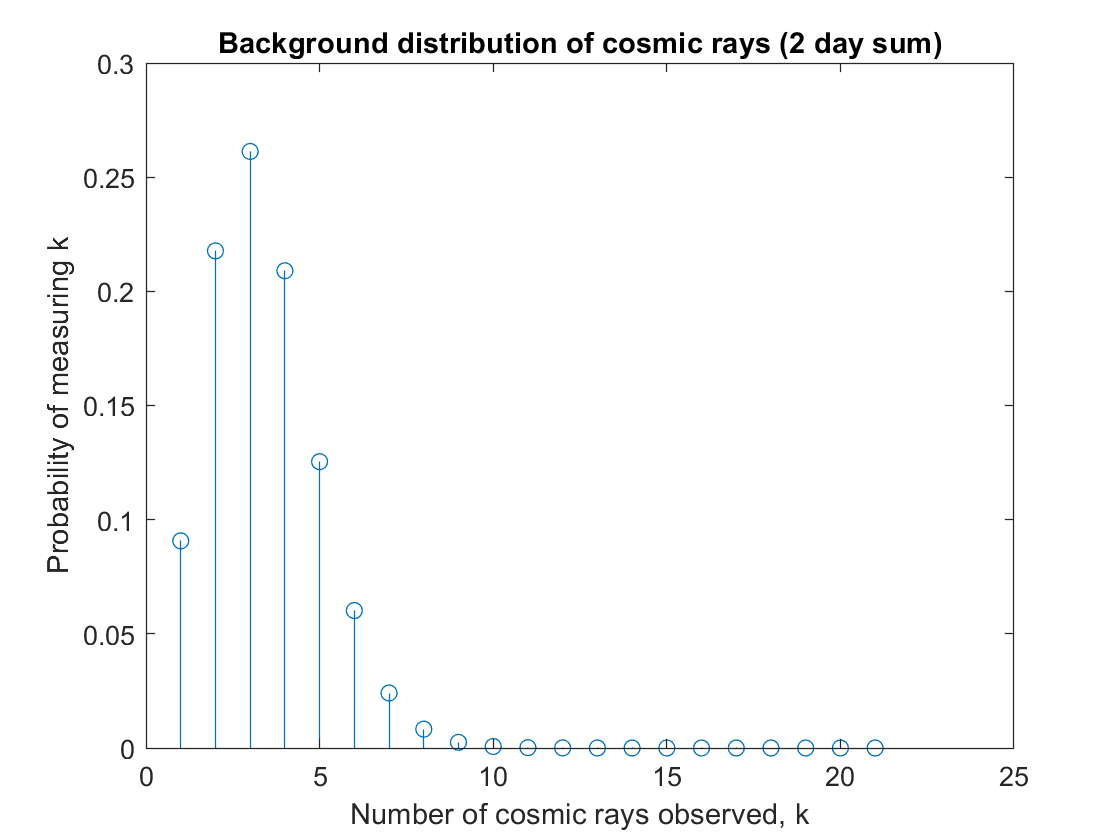

clf;
day_2_pdf = conv(pd_ys, pd_ys);
stem(1:length(day_2_pdf), day_2_pdf);
title('Background distribution of cosmic rays (2 day sum)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');

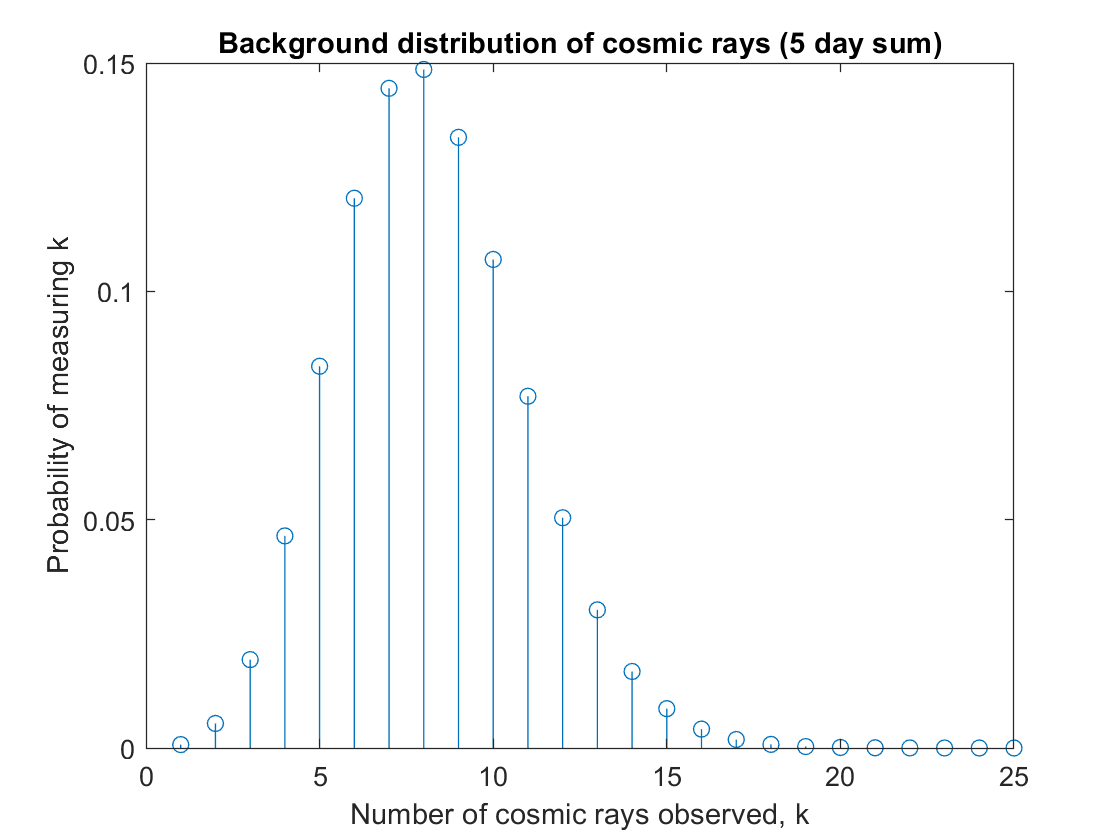

clf;
day_5_pdf = pd_ys;
for ii = 1:5
    day_5_pdf = conv(day_5_pdf, pd_ys);
end

stem(1:length(day_5_pdf), day_5_pdf);
title('Background distribution of cosmic rays (5 day sum)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
xlim([0 25])

We know that as one sums or averages a distribution many times, the convolved distribution will become Gaussian in shape. Is the Poisson distribution - summed over five days - Gaussian at this point?

The logarithm of a normally distributed variable will appear to be parabolic. Let's compare the shape of our convolved distribution with a Gaussian distribution:

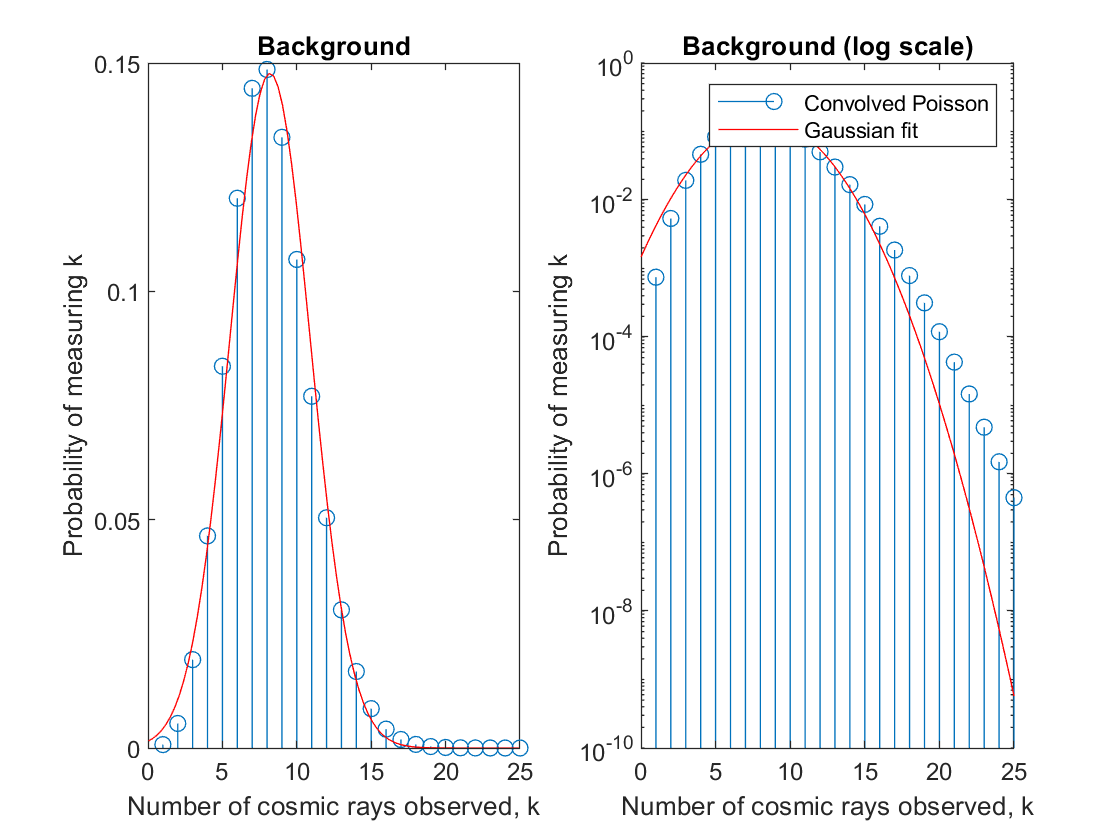

clf;
day_5_pdf = pd_ys;
for ii = 1:5
    day_5_pdf = conv(day_5_pdf, pd_ys);
end

subplot(1, 2, 1);
stem(1:length(day_5_pdf), day_5_pdf), hold on;
normxs = linspace(0, 60, 200);
normys = normpdf(normxs, 8.2, 2.7);
plot(normxs, normys, 'r-')
title('Background');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
xlim([0, 25]);

subplot(1, 2, 2);
stem(1:length(day_5_pdf), day_5_pdf), hold on;
plot(normxs, normys, 'r-')
set(gca,'YScale','log')
title('Background (log scale)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
legend('Convolved Poisson', 'Gaussian fit');
xlim([0, 25]);

Will the distribution look any more Gaussian after 15 days?

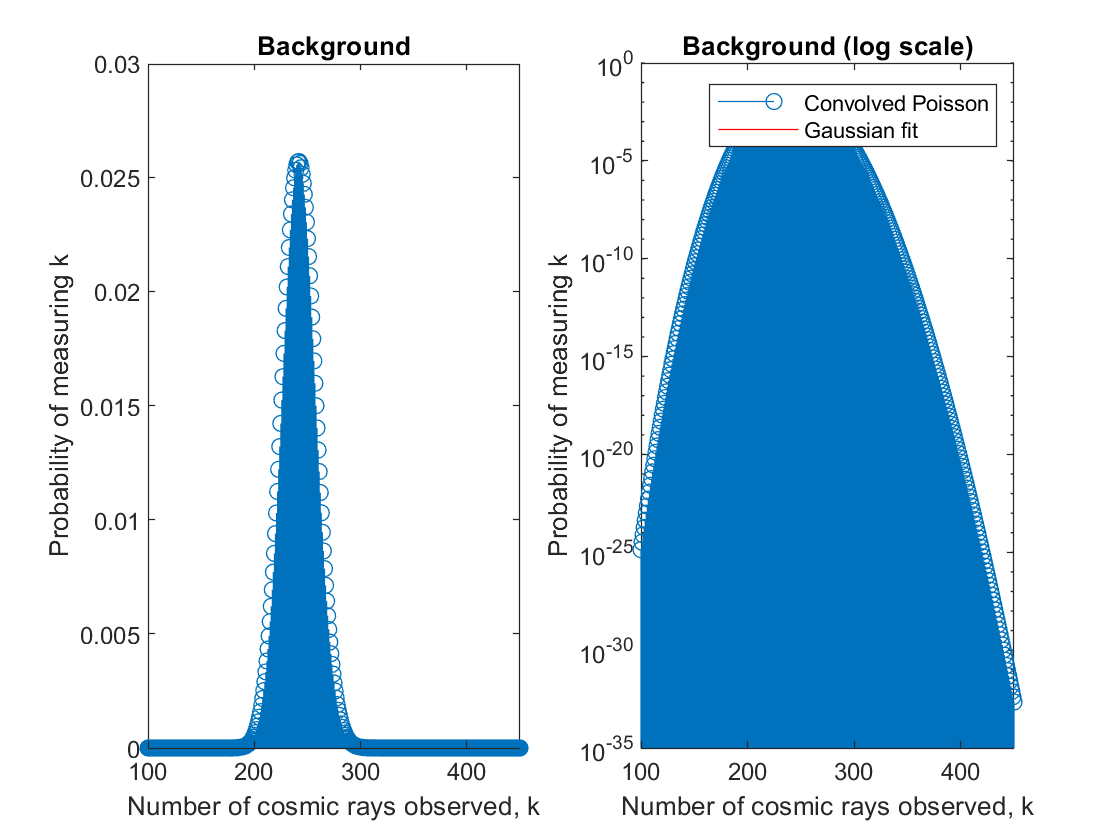

clf;
day_200_pdf = pd_ys;
for ii = 1:200
    day_200_pdf = conv(day_200_pdf, pd_ys);
end

subplot(1, 2, 1);
stem(1:length(day_200_pdf), day_200_pdf), hold on;
normxs = linspace(0, 60, 200);
normys = normpdf(normxs, 205, 44);
plot(normxs, normys, 'r-')
title('Background');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
xlim([100 450]);

subplot(1, 2, 2);
stem(1:length(day_200_pdf), day_200_pdf), hold on;
plot(normxs, normys, 'r-')
set(gca,'YScale','log')
title('Background (log scale)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');
legend('Convolved Poisson', 'Gaussian fit');
xlim([100 450]);

While the distribution not quite yet a Gaussian distribution, we can clearly see that by summing the distribution for more days, the distribution approaches a Gaussian distribution, as predicted by the Central Limit Theorem.

Now we will show the evolution of the distribution

Averages: convolve, then divide the x-axis by the number of distributions convolved

Convolution of a poisson is a poisson of the sum of lambdas

clf;
stem(xs, pd_ys);
title('Background distribution of cosmic rays');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');

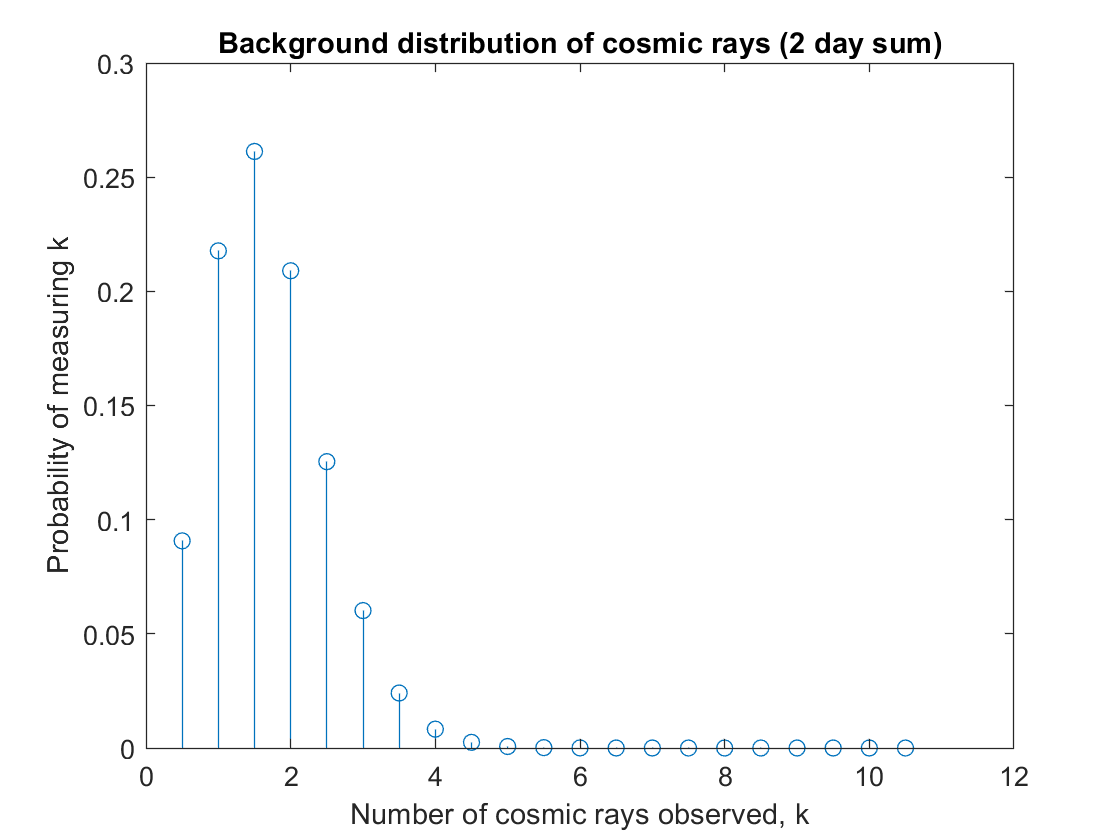


clf;
stem((1:length(day_2_pdf))/2, day_2_pdf);
title('Background distribution of cosmic rays (2 day sum)');
xlabel('Number of cosmic rays observed, k');
ylabel('Probability of measuring k');

D.)

n = 5;
signal = Y * n

signal = 20

Steps:

- Integrate the summed background pdf to find the probability that the background produced the signal.

- Subtract this from 1 to find the probabilty that the background did not produce the signal.

- Turn this probability into a sigma value using norminv

prob_signal = day_5_pdf(signal)

prob_signal = 1.1944e-04

sigma = norminv(prob_signal)

sigma = -3.6739

## Problem 2